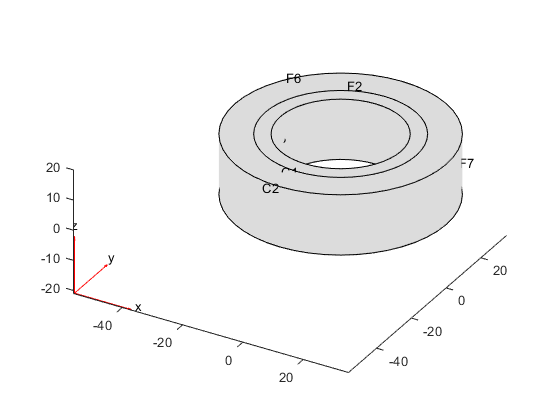

model = createpde('thermal');
geo = multicylinder([20,25,35],20,'Void',[1,0,0]);
model.Geometry= geo;
pdegplot(model,"FaceLabels","on","CellLabels","on")

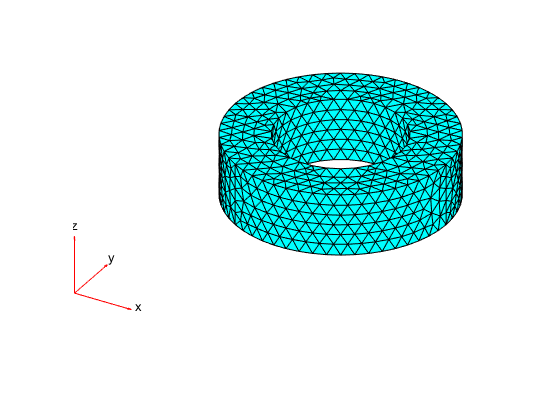

generateMesh(model);
pdemesh(model)

thermalProperties(model,"Cell",1,"ThermalConductivity",35);
thermalProperties(model, "Cell",2,"ThermalConductivity",40);
thermalBC(model,'Face',3,"Temperature",40);
thermalBC(model,"Face",7,"Temperature",5);

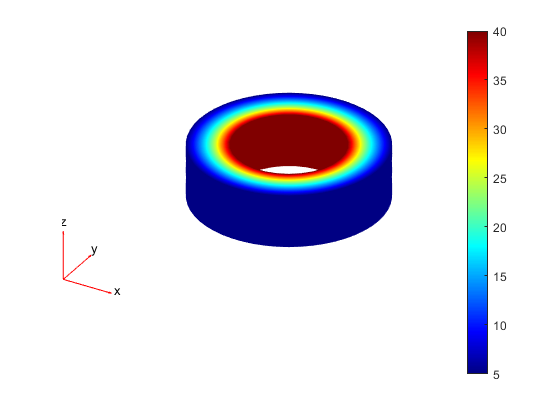

result = solve(model);
pdeplot3D(model,"ColorMapData",result.Temperature)